## 1.0 Importing subject EEG

clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load

## 1.1 Load and import file as EEGLAB matrix

% 1.1 Load and Crop Data (0 to 630 msec)
data_all_conds = struct();
time_ms_eeg = []; % Will populate on first load
testing_ch = 'Cz'; % 'CP3', 'F3', 'Cz', 'C3'
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Loading the 10th file in the sorted list as per original draft
    file_to_load = names_sorted{10}; 
    fprintf('Loading %s for condition: %s\n', file_to_load, condition);
    
    EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
    if isempty(fs)
        fs = EEG.srate;
       
    end
    % Rebuild time vector (assuming 3.5s epochs as in original draft)
    time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 

    % Crop to 0.50 - 1120 msec
    valid_time_idx = time_ms_eeg >= 0.500 & time_ms_eeg <= 1.120; 
    time_cropped = time_ms_eeg(valid_time_idx);
    
    % Extract odd/even trials based on condition
    if ismember(condition, {'BLT', 'P1', 'P2', 'P3'})
        epoch_trials = 1:2:EEG.trials;
    else
        epoch_trials = 2:2:EEG.trials;
    end
    allLabels = {EEG.chanlocs.labels};
    ch_idx = find(strcmp(allLabels, testing_ch)); % 'Cz', 'C3', 'CP3', 'F3'
    % Store cropped data: (Channels x Time x Trials)
    data_all_conds.(condition) = EEG.data(ch_idx, valid_time_idx, epoch_trials);
end

Loading binepochs filtered ICArej BLTAvgBOS5.set for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P1AvgBOS5.set for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P2AvgBOS5.set for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P3AvgBOS5.set for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


% Balance trials across conditions before concatenating
min_trials = 60;

% Concatenate all 4 conditions along the TIME dimension (Dimension 2)
% Resulting size: 32 Channels x (Time * 4 conditions) x Trials
data_concat = cat(2, data_all_conds.BLT(:,:,1:min_trials), ...
                     data_all_conds.P1(:,:,1:min_trials)); %, ...
                     ... % data_all_conds.P2(:,:,1:min_trials) , ...
                     % data_all_conds.P3(:,:,1:min_trials));

nTime_cropped = length(time_cropped);
total_samples = size(data_concat, 2);

fprintf('Concatenated data shape: %d channels x %d time points x %d trials\n', ...
        size(data_concat, 1), size(data_concat, 2), size(data_concat, 3));

Concatenated data shape: 1 channels x 636 time points x 60 trials


## 1.2 Visualizing the EEG for the first trial

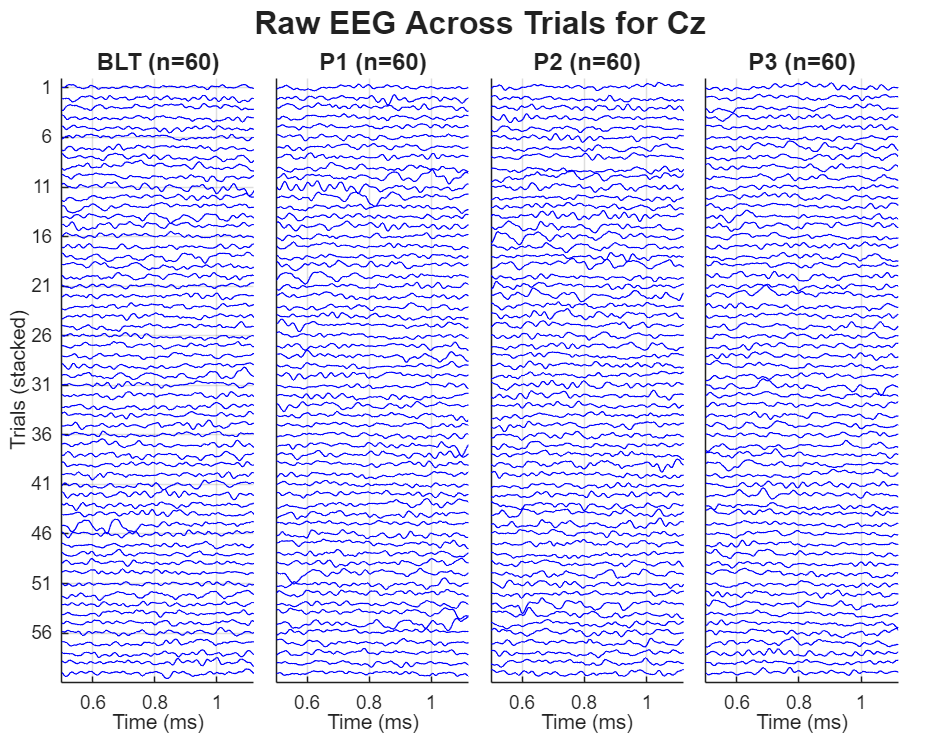

%% 1.2 Visualizing a Single Channel Across Trials (All Conditions)

% Define the specific channel you want to inspect (e.g., 1 for C3, 2 for CP3, etc.)
target_channel_idx = 1; 

% Automatically determine the number of conditions to plot based on your array
num_conds = length(conditions); 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 1800 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');

title(t, sprintf('Raw EEG Across Trials for %s', testing_ch), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; % vertical spacing between trials

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % Extract the specific channel across ALL times and ALL trials
    % Squeeze converts the [1 x Time x Trials] matrix into a [Time x Trials] matrix
    data_to_plot = squeeze(data_all_conds.(cond_name)(target_channel_idx, :, :));
    
    num_trials = size(data_to_plot, 2);
    display_trials = 1:1:num_trials;
    tick_positions = (num_trials - display_trials) * offset;
    
    nexttile;
    hold on
    for tr = 1:num_trials
        % Stack trials vertically
        plot(time_cropped, data_to_plot(:, tr) + (num_trials - tr)*offset, 'b', 'LineWidth', 1.0);
    end
    hold off
    
    % Fit the X-axis strictly to our cropped time window
    xlim([min(time_cropped), max(time_cropped)]); 
    ylim([-offset, num_trials*offset]);
    
    xlabel('Time (ms)');
    
    % Only show Y-axis labels on the very first (leftmost) plot
    if c == 1
        ylabel('Trials (stacked)');
        
        % Label every 5th trial to prevent Y-axis text from overlapping
        label_step = 5; 
        yticks(flip(tick_positions(1:label_step:end)));
        yticklabels(flip(string(display_trials(1:label_step:end))));
    else
        yticks([]); % Remove ticks for subsequent plots to maximize data visibility
    end
    
    set(gca,'FontSize',14);
    title(sprintf('%s (n=%d)', cond_name, num_trials), 'FontSize', 18);
    grid on;
end

% Marchenko–Pastur threshold
eig_vals = eig(cov(data_to_plot'));
[N, T] = size(data_to_plot);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
% num_sig_components = k; 
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 9 PCs


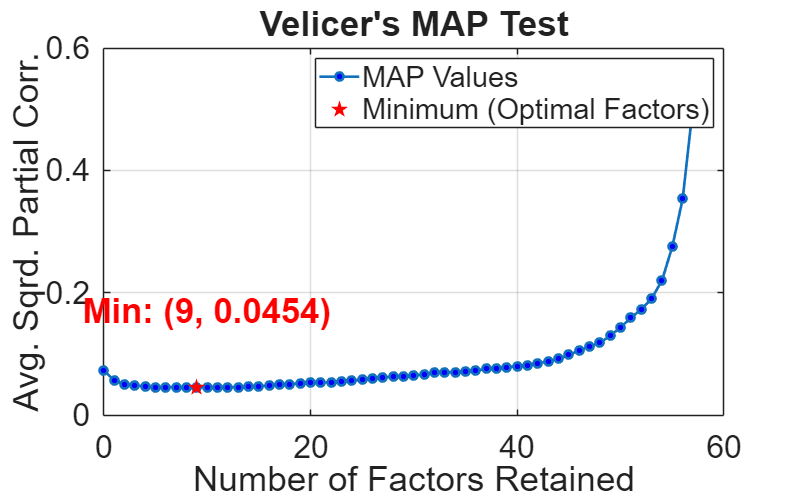

Velicer's MAP Test recommends retaining 9 factors.



[num_factors, map_values] = velicer_map(data_to_plot');


function [num_factors, map_values] = velicer_map(data)
% VELICER_MAP Determines the number of factors to retain using Velicer's MAP test.
%
% Inputs:
%   data - An (n x p) matrix of raw data (n observations, p variables).
%
% Outputs:
%   num_factors - The optimal number of factors to retain.
%   map_values  - A vector containing the MAP values at each step (from 0 to p-1 factors).

    % 1. Compute the correlation matrix
    R = corrcoef(data);
    p = size(R, 1);
    
    % 2. Perform Eigenvalue Decomposition
    [eigvec, eigval_mat] = eig(R);
    eigval = diag(eigval_mat);
    
    % Sort eigenvalues and eigenvectors in descending order
    [eigval, idx] = sort(eigval, 'descend');
    eigvec = eigvec(:, idx);
    
    % Initialize array to store the MAP values
    map_values = zeros(1, p);
    
    % 3. Step 0: Calculate average squared correlation (no factors partialled out)
    R_off_diag = R - eye(p);
    map_values(1) = sum(R_off_diag(:).^2) / (p * (p - 1));
    
    % 4. Loop to partial out 1 to p-1 components
    for m = 1:(p-1)
        % Calculate the loadings for m components
        A = eigvec(:, 1:m) * diag(sqrt(eigval(1:m)));
        
        % Reproduce the correlation matrix from m components
        part_cov = R - (A * A');
        
        % Compute the partial correlation matrix
        d = diag(part_cov);
        inv_sqrt_d = diag(1 ./ sqrt(d));
        R_partial = inv_sqrt_d * part_cov * inv_sqrt_d;
        
        % Isolate off-diagonal elements
        R_partial_off = R_partial - eye(p);
        
        % Calculate the average squared partial correlation
        map_values(m+1) = sum(R_partial_off(:).^2) / (p * (p - 1));
    end
    
    % 5. Find the minimum MAP value
    % Note: MATLAB is 1-indexed, so index 1 represents 0 factors.
    [min_val, min_idx] = min(map_values);
    num_factors = min_idx - 1;
    
    % 6. Optional: Plot the results to visualize the minimum
    figure('Position',[50 50 800 500]);
    plot(0:(p-1), map_values, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
    hold on;
    plot(num_factors, map_values(min_idx), 'rp', 'MarkerSize', 12, 'MarkerFaceColor', 'r'); % Highlight minimum
    coordinate_text = sprintf('  Min: (%d, %.4f)', num_factors, min_val);
    text(num_factors, 0.2, coordinate_text, ...
        'VerticalAlignment', 'top', ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 26, ...
        'FontWeight', 'bold', ...
        'Color', 'r');
    xlabel('Number of Factors Retained');
    ylabel('Avg. Sqrd. Partial Corr.');
    title('Velicer''s MAP Test');
    legend('MAP Values', 'Minimum (Optimal Factors)');
    set(gca,'FontSize',24);
    grid on;
    hold off;
    
    % Output the result to the console
    fprintf('Velicer''s MAP Test recommends retaining %d factors.\n', num_factors);
end

### 2.0 Parameter setup for dPCA

% 2.0 Label Generation and Trial Splitting

% 1. Create the One-Hot Encoded Time Labels
% 0: 0-50 msec (Bottom-up)
% 1: 50-630 msec (Top-down)
label_vector_single = zeros(1, nTime_cropped);
label_vector_single(time_cropped > 50) = 1; 

% Replicate this label vector for all 4 concatenated conditions
time_labels_concat = repmat(label_vector_single, 1, 4);

% 2. Split data by whole trials (80% Train, 20% Test)
num_train_trials = floor(0.8 * min_trials);
data_concat = squeeze(data_concat);
data_train = data_concat(:, 1:num_train_trials);
data_test = data_concat(:, num_train_trials+1:end);

fprintf('The X_train dimension is %dx%d \n', size(data_train));

The X_train dimension is 636x48 


### 2.1 Run dPCA

% 2.1 Run dPCA

% Prepare X for dPCA: (Channels x Time x 1)
X_dpca = zeros(size(data_train, 2), size(data_train, 1), 1);
X_dpca(:,:) = data_train'; % trial x time -> the first dimension will be reduced

%ToDo: double check dPCA.

% Number of latent variables (components) to keep
k = 3; % num_factors

% Run dPCA (assuming standard dpca syntax)
[W, V, whichMarg] = dpca(X_dpca, k); 

% Project test data into the latent space
% Z_dpca shape: (Latent Variables i x Samples s)
Z_dpca = W' * data_train';
Z_dpca = Z_dpca';

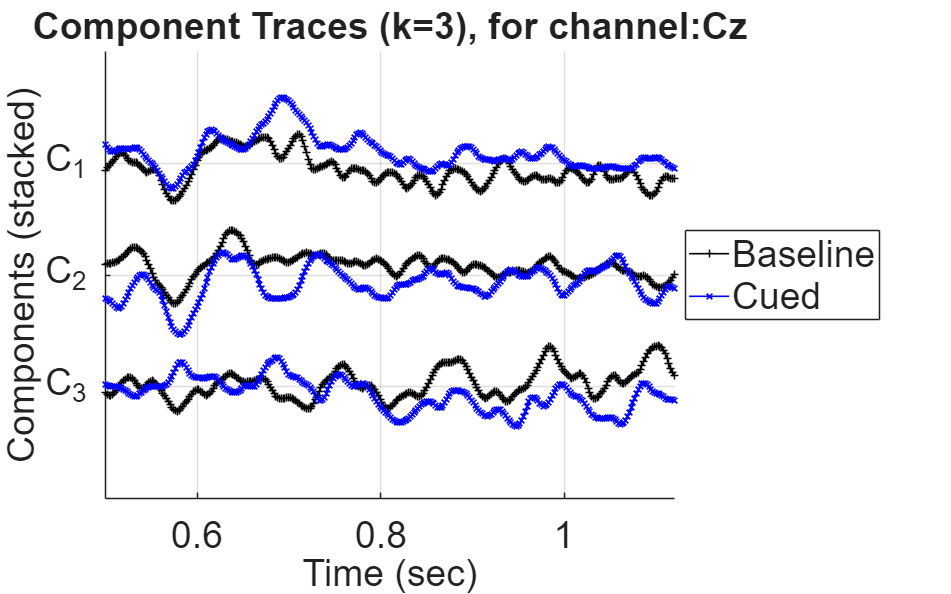

% 2. Component Tracesfor the first 1 seconds (matching your previous xlim)

time_vec = [time_cropped, time_cropped];
num_comps_plot = k;

% Define time vector ;

% Setup Figure
fig2 = figure('Position', [50 50 1200 750]);
hold on;

% --- Styling ---
% Calculate offset based on data range to prevent excessive overlap
% If the components are z-scored, an offset of 5-10 usually works well.
% Here we use a fixed offset similar to your EEG example.
offset = max(std(Z_dpca(:, 1:num_comps_plot), 0, 1)) * 6; 
if offset == 0 || isnan(offset), offset = 10; end % Fallback

for pc = 1:num_comps_plot
    % Extract data for this component
    trace = Z_dpca(:, pc);
    
    % Plot each component stacked (Component 1 at the top)
    % Using (num_comps_plot - pc) ensures C_1 is at the top of the y-axis
    y_shift = (num_comps_plot - pc) * offset;
    plot(time_cropped, trace(1:nTime_cropped) + y_shift, 'Color', 'k', 'Marker','+','LineWidth', 1.2, 'HandleVisibility', 'off');
    plot(time_cropped, trace(nTime_cropped+1:end) + y_shift, 'Color', 'b', 'Marker','x', 'LineWidth', 1.2, 'HandleVisibility', 'off');
end

% Plotting NaN ensures nothing is drawn, but the legend can still read the color/style
h_BLT = plot(NaN, NaN, 'Color',  'k', 'Marker','+', 'LineWidth', 1.2, 'DisplayName', 'Baseline');
h_P1  = plot(NaN, NaN, 'Color', 'b','Marker','x', 'LineWidth', 1.2, 'DisplayName', 'Cued');

hold off;

% --- Formatting ---
% xlim([0 t_plot_sec]);
ylim([-offset, num_comps_plot * offset]);
xlim([0.5 1.12]);
xlabel('Time (sec)');
ylabel('Components (stacked)');
title(['Component Traces (k=' num2str(num_comps_plot) ')' ', for channel:' testing_ch]);

% Set ticks to show component numbers clearly
yticks((0:num_comps_plot-1) * offset);
yticklabels(arrayfun(@(c) sprintf('C_{%d}', num_comps_plot - c), ...
    0:num_comps_plot-1, 'UniformOutput', false));
legend([h_BLT, h_P1], 'Location', 'eastoutside');
grid on;
set(findall(fig2, '-property', 'FontSize'), 'FontSize', 28);

##  b+3.0 Sliding Window (20 msec) Latent Plotting

% window_ms = 20;
% samples_per_window = round((window_ms / 1000) * fs); 
% 
% % Non-overlapping sliding window across the concatenated time series
% num_windows = floor(total_samples / samples_per_window);
% num_latents = size(Z_dpca, 2); % Total number of latent variables k
% 
% % Prepare an invisible figure for fast saving, made wide for the tiled layout
% fig = figure('Visible', 'off', 'Position', [100, 100, 1600, 900]); 
% 
% fprintf('Generating and saving %d sliding window plots...\n', num_windows);
% 
% % Determine grid size for subplots (e.g., if 8 latents, we need 7 plots)
% num_plots = num_latents - 1;
% grid_cols = ceil(sqrt(num_plots));
% grid_rows = ceil(num_plots / grid_cols);
% 
% for w = 1:num_windows
%     clf(fig); % Clear figure for the new window
% 
%     % Define sample indices (s) for the current window
%     s_start = (w-1) * samples_per_window + 1;
%     s_end   = s_start + samples_per_window - 1;
% 
%     % Determine the dominant cognitive state (0 or 1) for this window
%     current_label = mode(time_labels_concat(s_start:s_end));
% 
%     % Color categories: 0-50 msec vs 50-630 msec
%     if current_label == 0
%         state_str = '0-50 msec (Bottom-Up Sensory)';
%         color_theme = [0.4 0.6 0.8]; % Light Blue to match your reference
%     else
%         state_str = '50-630 msec (Top-Down Cognitive)';
%         color_theme = [0.85 0.4 0.1]; % Orange to match your reference
%     end
% 
%     % Initialize the tiled layout
%     t = tiledlayout(grid_rows, grid_cols, 'TileSpacing', 'compact', 'Padding', 'compact');
%     title(t, sprintf('Latent Space Projections | Window %d | State: %s', w, state_str), ...
%           'FontSize', 24, 'FontWeight', 'bold');
% 
%     % Extract Latent variable i=1 for the x-axis for the current samples s
%     x_window = Z_dpca(s_start:s_end,1);
% 
%     % Loop through the remaining latent variables i
%     for i = 2:num_latents
%         nexttile;
%         hold on;
% 
%         % 1. Plot the "Ghost" Background (All samples s)
%         % This shows the full manifold in light gray for structural context
%         plot(Z_dpca(:,1), Z_dpca(:,i), '.', 'Color', [0.75 0.75 0.75], 'MarkerSize', 4);
% 
%         % 2. Extract Latent variable i for the y-axis for current samples s
%         y_window = Z_dpca(s_start:s_end, i);
% 
%         % 3. Highlight the current window's trajectory
%         plot(x_window, y_window, '-o', 'LineWidth', 2, 'Color', color_theme, ...
%              'MarkerFaceColor', color_theme, 'MarkerEdgeColor', color_theme, 'MarkerSize', 5);
% 
%         % Formatting
%         xlabel('Latent Dim. 1', 'FontSize', 12, 'FontWeight', 'bold');
%         ylabel(sprintf('Latent Dim. %d', i), 'FontSize', 12, 'FontWeight', 'bold');
%         grid on;
% 
%         % Set static axis limits based on the global max/min of the respective latents
%         xlim([min(Z_dpca(:,1))*1.1, max(Z_dpca(:,1))*1.1]);
%         ylim([min(Z_dpca(:,i))*1.1, max(Z_dpca(:,i))*1.1]);
% 
%         hold off;
%     end
% 
%     % Save the plot to your longitudinal_dPCA subfolder
%     save_name = fullfile(output_path, sprintf('Latent_1_vs_Others_win%03d.png', w));
%     saveas(fig, save_name);
% end
% fprintf('Pipeline complete. Plots saved to output directory.\n');

### 2.0 dPCA across channels

%% 1.1 Load and Crop Data (0.50 to 1.12 sec)
data_all_conds = struct();
time_ms_eeg = []; % Will populate on first load

for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Loading the 10th file in the sorted list as per original draft
    file_to_load = names_sorted{10}; 
    fprintf('Loading %s for condition: %s\n', file_to_load, condition);
    
    EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
    if isempty(fs)
        fs = EEG.srate;
    end
    
    % Rebuild time vector (assuming 3.5s epochs as in original draft)
    time_ms_eeg = linspace(0, 3.5, size(EEG.data, 2)); 

    % Crop to 0.500 - 1.120 sec
    valid_time_idx = time_ms_eeg >= 0.500 & time_ms_eeg <= 1.120; 
    time_cropped = time_ms_eeg(valid_time_idx);
    
    % Extract odd/even trials based on condition
    if ismember(condition, {'BLT', 'P1', 'P2', 'P3'})
        epoch_trials = 1:2:EEG.trials;
    else
        epoch_trials = 2:2:EEG.trials;
    end
    
    % KEEP ALL CHANNELS: Store cropped data as (Channels x Time x Trials)
    data_all_conds.(condition) = EEG.data(:, :, epoch_trials);
end

Loading binepochs filtered ICArej BLTAvgBOS5.set for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P1AvgBOS5.set for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P2AvgBOS5.set for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P3AvgBOS5.set for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 2.1 Visualize all channels for all conditions

target_trial = 1; % You can loop this or change it to test different trials

% Resulting size: 32 Channels x (Time_BLT + Time_P1) x Trials
data_concat_all = cat(3, data_all_conds.BLT(:,:,1:target_trial), ...
                     data_all_conds.P1(:,:,1:target_trial), ...
                     data_all_conds.P2(:,:,1:target_trial), ...
                     data_all_conds.P3(:,:,1:target_trial));

total_samples = size(data_concat_all, 2);

fprintf('Concatenated data shape: %d channels x %d time points x %d conditions\n', ...
        size(data_concat_all, 1), size(data_concat_all, 2), size(data_concat_all, 3));

Concatenated data shape: 32 channels x 1792 time points x 4 conditions


% Safely extract channel labels for the Y-axis
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    display_channels_str = cellstr(num2str((1:size(X_plot, 1))')); 
end

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;

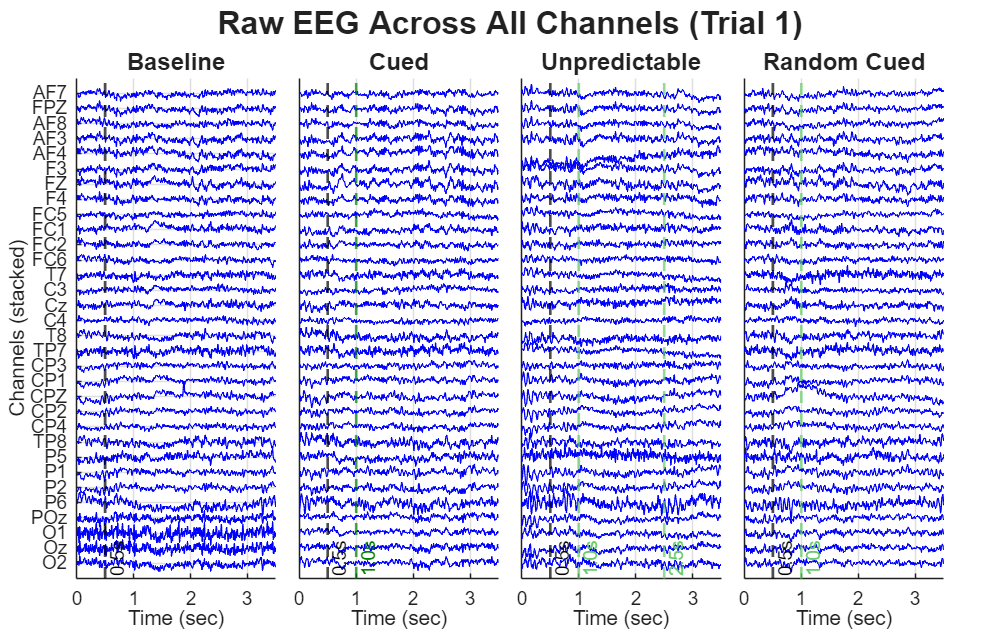

%% Visualizing All Channels Across Time (Subplots per Condition)
target_trial = 1; % Define which trial you want to inspect

% Safely extract channel labels for the Y-axis
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT, 1))')); 
end

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;
num_conds = length(conditions); 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG Across All Channels (Trial %d)', target_trial), 'FontSize', 24, 'FontWeight', 'bold');

% Offset: Use 30 for raw EEG microvolts, or reduce to 5 if using scaled/z-scored data
offset = 30; 
tick_positions = (num_channels_plot - display_channels) * offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % Extract [Channels x Time] for the specific target trial
    data_to_plot = data_all_conds.(cond_name)(:, :, target_trial);
    
    nexttile;
    hold on
    
    % 1. Plot the Channels
    for ch = 1:num_channels_plot
        % Stack channels vertically and strictly use blue ('b')
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    % 2. Add Vertical Event Lines
    % All conditions get a dashed vertical line at time 0.5 sec
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    
    % Condition-specific event lines
    if strcmp(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off
    
    % Fit the X-axis strictly to our cropped time window
    % (Ensure your time_cropped vector goes up to at least 2.5s to see the P2 line!)
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    
    xlabel('Time (sec)'); 
    
    % Only show Y-axis labels on the very first (leftmost) plot
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); % Remove ticks for subsequent plots to maximize data visibility
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLT')
        plot_name = 'Baseline';
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    grid on;
end

## 2.3 Balance and Concatenate (BLT and P1)

% Ensure we don't exceed the bounds of whichever condition has fewer trials
min_trials = min(size(data_all_conds.BLT, 3), size(data_all_conds.P1, 3));
valid_time_idx = time_ms_eeg >= 0.500 & time_ms_eeg <= 1.120; 
time_cropped = time_ms_eeg(valid_time_idx);
% Concatenate along the TIME dimension (Dimension 2)
% Resulting size: 32 Channels x (Time_BLT + Time_P1) x Trials
data_concat_ch = cat(2, data_all_conds.BLT(:,valid_time_idx,1:min_trials), ...
                     data_all_conds.P1(:,valid_time_idx,1:min_trials)); %, ...
                    ... % data_all_conds.P2(:,:,1:min_trials) , ...
                    % data_all_conds.P3(:,time_cropped,1:min_trials));

total_samples = size(data_concat_ch, 2);

fprintf('Concatenated data shape: %d channels x %d time points x %d trials\n', ...
        size(data_concat_ch, 1), size(data_concat_ch, 2), size(data_concat_ch, 3));

Concatenated data shape: 32 channels x 636 time points x 60 trials


## Extract Single Trial formatted as (Channels x Time x 1)


target_trial = 1; % You can loop this or change it to test different trials

% Extract the specific trial: yields a 2D matrix of (Channels x Time)
single_trial_data = data_concat_ch(:, :, target_trial); % ch x time

% 2. Cast to DOUBLE precision (Crucial for matrix inversion)
X_single_trial = double(single_trial_data);

% 3. Globally scale the data to stabilize variance 
% (Dividing by global std preserves relative amplitude between channels)
% Compute global standard deviation across all elements (scalar).
% std(X_single_trial(:)) computes std over the entire matrix (not along rows or columns).
global_std = std(X_single_trial(:));
X_single_trial = X_single_trial / global_std;

% 4. Append the singleton 3rd dimension so dPCA knows Time is dimension 2
X_dpca_input = reshape(X_single_trial, size(X_single_trial, 1), size(X_single_trial, 2), 1);

fprintf('Extracted Trial %d shape ready for dPCA: %d channels x %d time points x 1 trial\n', ...
        target_trial, size(X_dpca_input, 1), size(X_dpca_input, 2));

Extracted Trial 1 shape ready for dPCA: 32 channels x 636 time points x 1 trial


## 2.4 Visualizing All Channels Across Time 

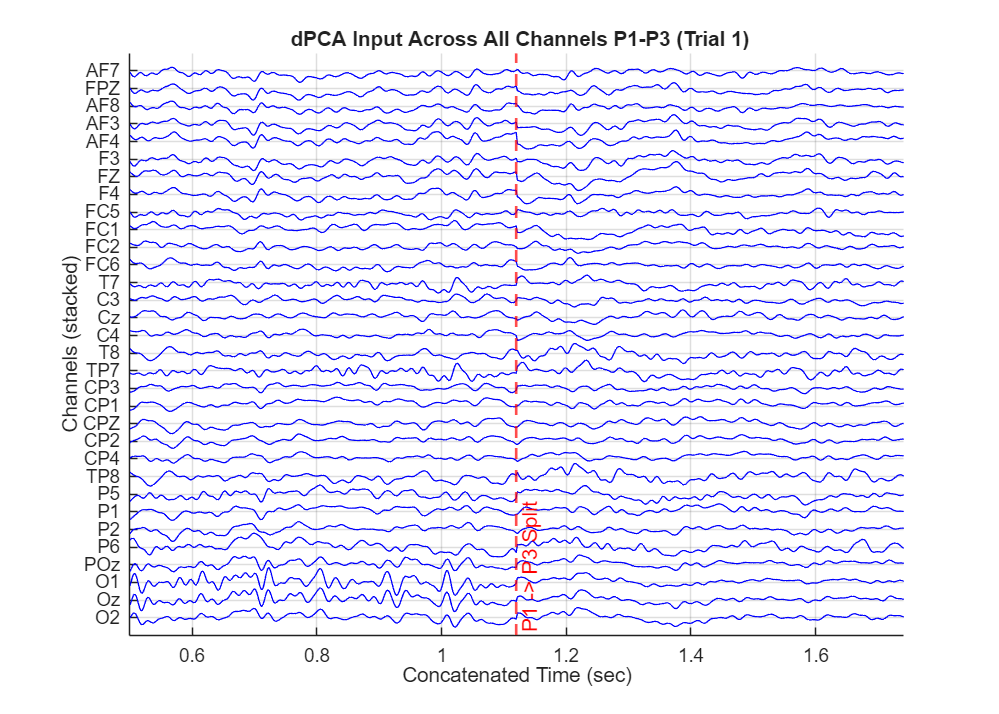

%% 1.2 Visualizing the Pre-Processed dPCA Input (All Channels)

% Extract the 2D matrix by squeezing out the singleton 3rd dimension
% X_plot shape: (Channels x Time)
X_plot = squeeze(X_dpca_input); 

% Safely extract channel labels for the Y-axis
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    display_channels_str = cellstr(num2str((1:size(X_plot, 1))')); 
end

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;

% Create a continuous time vector for the concatenated data
nTime_single = length(time_cropped);
dt = time_cropped(2) - time_cropped(1);

% Ensure time_cropped starts at 0.500 and ends at 1.120 as earlier
% Build concatenated time that runs from 0.500 to 1.740 (i.e., 0.500->1.120 then 1.120->1.740)
% We create the second segment by shifting time_cropped so its start is immediately after the first end.
first_segment = time_cropped;
second_segment = time_cropped + (time_cropped(end) - time_cropped(1)) + dt; 
% Concatenate
time_concat = [first_segment, second_segment];

% Recompute nTime_single in case it's used elsewhere as the split point
nTime_single = length(first_segment);

% Set up a single wide figure (no tiled layout needed since it's one concatenated block)
figure('Position',[50 50 1400 1000])
title(sprintf(' dPCA Input Across All Channels P1-P3 (Trial %d)', target_trial), ...
      'FontSize', 24, 'FontWeight', 'bold');

% Adjusted offset for globally scaled data (standard deviation ~ 1)
offset = 5; 
tick_positions = (num_channels_plot - display_channels) * offset;

hold on
for ch = 1:num_channels_plot
    % Stack channels vertically and strictly use blue ('b')
    plot(time_concat, X_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
end

% Add a vertical boundary line to show where BLT ends and P1 begins
split_time = time_concat(nTime_single);
xline(split_time, 'r--', 'P1 -> P3 Split', 'LineWidth', 2, 'FontSize', 16, 'LabelVerticalAlignment', 'bottom');

hold off

% Fit the X-axis strictly to our concatenated time window
xlim([min(time_concat), max(time_concat)]); 
ylim([-offset, num_channels_plot*offset]);

xlabel('Concatenated Time (sec)'); 
ylabel('Channels (stacked)');
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str)));

set(gca,'FontSize',14);
grid on;

% Marchenko–Pastur threshold
eig_vals = eig(cov(X_dpca_input'));
[N, T] = size(X_dpca_input);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
% num_sig_components = k; 
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 5 PCs


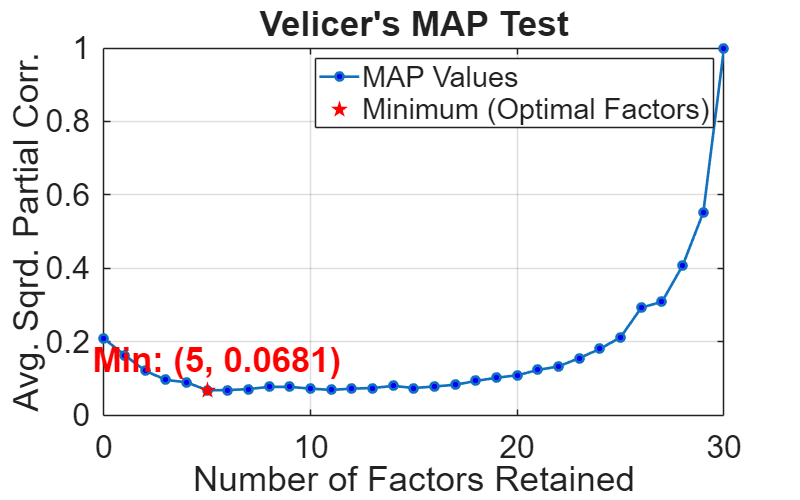

Velicer's MAP Test recommends retaining 5 factors.



[num_factors, map_values] = velicer_map(X_dpca_input');

## 2.5 Run dPCA across channels



% Number of latent variables (components) to keep
k = num_sig_components; % num_factors

% Run dPCA (assuming standard dpca syntax)
[W_ch, V, whichMarg] = dpca(X_dpca_input, k); 

Matrix close to singular, using tiny regularization, lambda = 1e-10



% Project test data into the latent space
% Z_dpca shape: (Latent Variables i x Samples s)
Z_dpca_ch = W_ch' * X_dpca_input;
Z_dpca_ch = Z_dpca_ch';

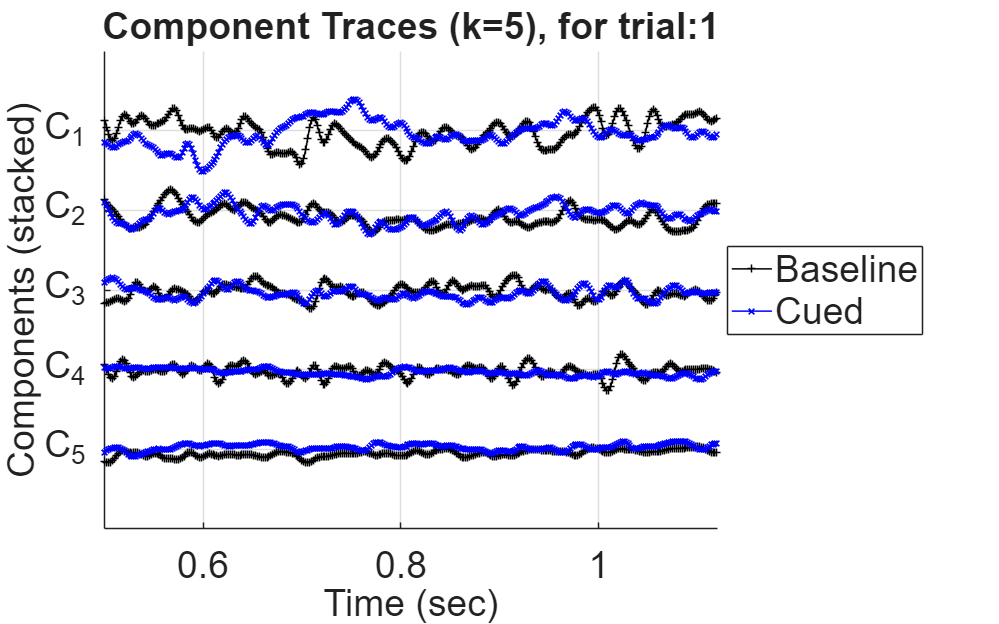

time_vec = [time_cropped, time_cropped];
num_comps_plot = k;

% Define time vector ;

% Setup Figure
fig2 = figure('Position', [50 50 1200 750]);
hold on;

% --- Styling ---
% Calculate offset based on data range to prevent excessive overlap
% If the components are z-scored, an offset of 5-10 usually works well.
% Here we use a fixed offset similar to your EEG example.
offset = max(std(Z_dpca_ch(:, 1:num_comps_plot), 0, 1)) * 6; 
if offset == 0 || isnan(offset), offset = 10; end % Fallback

for pc = 1:num_comps_plot
    % Extract data for this component
    trace = Z_dpca_ch(:, pc);
    
    % Plot each component stacked (Component 1 at the top)
    % Using (num_comps_plot - pc) ensures C_1 is at the top of the y-axis
    y_shift = (num_comps_plot - pc) * offset;
    plot(time_cropped, trace(1:nTime_cropped) + y_shift, 'Color', 'k', 'Marker','+','LineWidth', 1.2, 'HandleVisibility', 'off');
    plot(time_cropped, trace(nTime_cropped+1:end) + y_shift, 'Color', 'b','Marker','x', 'LineWidth', 1.2, 'HandleVisibility', 'off');
end

% Plotting NaN ensures nothing is drawn, but the legend can still read the color/style
h_BLT = plot(NaN, NaN, 'Color',  'k', 'Marker','+', 'LineWidth', 1.2, 'DisplayName', 'Baseline');
h_P1  = plot(NaN, NaN, 'Color', 'b',  'Marker','x','LineWidth', 1.2, 'DisplayName', 'Cued');

hold off;

% --- Formatting ---
% xlim([0 t_plot_sec]);
ylim([-offset, num_comps_plot * offset]);
xlim([0.5 1.12]);
xlabel('Time (sec)');
ylabel('Components (stacked)');
title(['Component Traces (k=' num2str(num_comps_plot) ')' ', for trial:' num2str(target_trial)]);

% Set ticks to show component numbers clearly
yticks((0:num_comps_plot-1) * offset);
yticklabels(arrayfun(@(c) sprintf('C_{%d}', num_comps_plot - c), ...
    0:num_comps_plot-1, 'UniformOutput', false));
legend([h_BLT, h_P1], 'Location', 'eastoutside');
grid on;
set(findall(fig2, '-property', 'FontSize'), 'FontSize', 28);

## 3.0 Reshape the conditions to have all trials and plot average with std dev.

valid_time_idx_BLT = time_ms_eeg >= 0.5000 & time_ms_eeg <= 1.1200; 
valid_time_idx_P13 = time_ms_eeg >= 1.0000 & time_ms_eeg < 1.621; 
valid_time_idx_P12 = time_ms_eeg >= 1.0000 & time_ms_eeg < 3.121; 

time_cropped_BLT = time_ms_eeg(valid_time_idx_BLT);
time_cropped_P12 = time_ms_eeg(valid_time_idx_P12);
time_cropped_P13 = time_ms_eeg(valid_time_idx_P13);

% 1. Determine the maximum number of balanced trials
min_trials = size(data_all_conds.P1, 3);

% 2. Generate independent random trial permutations
% (Using rng(42) ensures you can reproduce this exact "random" plot for your adviser later)
rng(42); 
rand_idx_BLT = randperm(num_trials_BLT, min_trials);
rand_idx_P1  = randperm(num_trials_P1, min_trials);

% 3. Concatenate using the randomized trial indices
% Now, Trial 1 of BLT is concatenated with a completely random Trial M of P1
data_concat_all = cat(2, ...
    ... % data_all_conds.BLT(:, valid_time_idx_BLT, rand_idx_BLT), ...
    data_all_conds.P1(:, valid_time_idx_P13, rand_idx_P1), ...
    ... % data_all_conds.P2(:, valid_time_idx_P12, rand_idx_P1)
    data_all_conds.P3(:, valid_time_idx_P13, rand_idx_P1));

total_samples = size(data_concat_all, 2);

fprintf('Concatenated data shape: %d channels x %d time points x %d trials\n', ...
        size(data_concat_all, 1), size(data_concat_all, 2), size(data_concat_all, 3));

Concatenated data shape: 32 channels x 636 time points x 60 trials


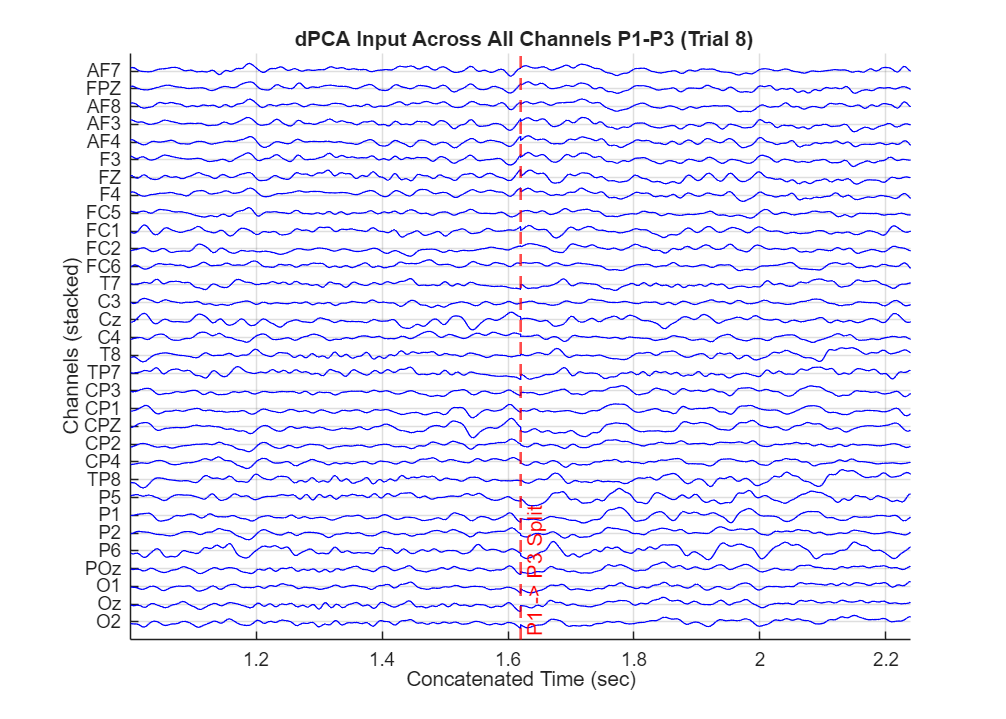

% Plot the raw traces for the first two trials
%% 1.2 Visualizing the Pre-Processed dPCA Input (All Channels)

% Extract the 2D matrix by squeezing out the singleton 3rd dimension
target_trial = 8;
% X_plot shape: (Channels x Time)
X_plot = squeeze(data_concat_all(:,:,target_trial)); 

% Safely extract channel labels for the Y-axis
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    display_channels_str = cellstr(num2str((1:size(X_plot, 1))')); 
end

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;

% Create a continuous time vector for the concatenated data
dt = time_cropped_BLT(2) - time_cropped_BLT(1);

% Ensure time_cropped starts at 0.500 and ends at 1.120 as earlier
% Build concatenated time that runs from 0.500 to 1.740 (i.e., 0.500->1.120 then 1.120->1.740)
% We create the second segment by shifting time_cropped so its start is immediately after the first end.
first_segment = time_cropped_P13;
second_segment = time_cropped_P13 + (time_cropped_P13(end) - time_cropped_P13(1)); 
% Concatenate
time_concat = [first_segment, second_segment];

% Recompute nTime_single in case it's used elsewhere as the split point
nTime_single = length(first_segment);

% Set up a single wide figure (no tiled layout needed since it's one concatenated block)
figure('Position',[50 50 1400 1000])
title(sprintf(' dPCA Input Across All Channels P1-P3 (Trial %d)', target_trial), ...
      'FontSize', 24, 'FontWeight', 'bold');

% Adjusted offset for globally scaled data (standard deviation ~ 1)
offset = 30; 
tick_positions = (num_channels_plot - display_channels) * offset;

hold on
for ch = 1:num_channels_plot
    % Stack channels vertically and strictly use blue ('b')
    plot(time_concat, X_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
end

% Add a vertical boundary line to show where BLT ends and P1 begins
split_time = time_concat(nTime_single);
xline(split_time, 'r--', 'P1 -> P3 Split', 'LineWidth', 2, 'FontSize', 16, 'LabelVerticalAlignment', 'bottom');

hold off

% Fit the X-axis strictly to our concatenated time window
xlim([min(time_concat), max(time_concat)]); 
ylim([-offset, num_channels_plot*offset]);

xlabel('Concatenated Time (sec)'); 
ylabel('Channels (stacked)');
yticks(flip(tick_positions));
yticklabels(flip(string(display_channels_str)));

set(gca,'FontSize',14);
grid on;

% 3. Globally scale the data to stabilize variance 
% (Dividing by global std preserves relative amplitude between channels)
% Compute global standard deviation across all elements (scalar).
% std(X_single_trial(:)) computes std over the entire matrix (not along rows or columns).
global_std_all = std(data_concat_all(:));
data_concat_all = data_concat_all / global_std_all;

% reshape ch x (time x trial) 
% 4. Append the singleton 3rd dimension so dPCA knows Time is dimension 2
X_dpca_input = reshape(data_concat_all, size(data_concat_all, 1), size(data_concat_all, 2)* size(data_concat_all, 3), 1);
X_dpca_input = double(squeeze(X_dpca_input));
fprintf('Concatenated data shape: %d channels x %d (time points x trials) \n', ...
        size(X_dpca_input, 1), size(X_dpca_input, 2));

Concatenated data shape: 32 channels x 38160 (time points x trials) 


% Marchenko–Pastur threshold
eig_vals = eig(cov(X_dpca_input'));
[N, T] = size(X_dpca_input);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
% num_sig_components = k; 
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 3 PCs


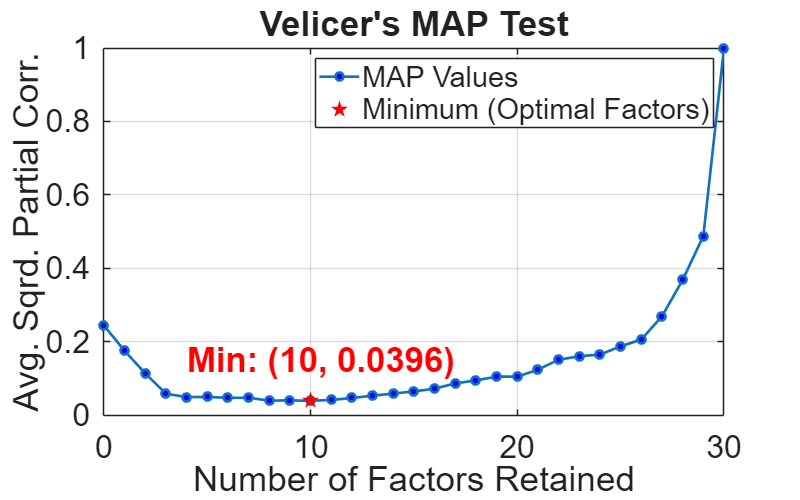

Velicer's MAP Test recommends retaining 10 factors.



[num_factors, map_values] = velicer_map(X_dpca_input');

% do dPCA
% Number of latent variables (components) to keep
k = num_sig_components; % num_factors

% Run dPCA (assuming standard dpca syntax)
[W_all, V, whichMarg] = dpca(X_dpca_input, k); 

Matrix close to singular, using tiny regularization, lambda = 1e-10


% Project test data into the latent space
% Z_dpca shape: (Latent Variables i x Samples s)
Z_dpca_all = W_all' * X_dpca_input;

% Reshape components back to original form
Z_dpca_all_reshape = reshape(Z_dpca_all,size(Z_dpca_all,1), total_samples,size(data_concat_all, 3));
% cal mean and std dev
Z_dpca_all_mean = mean(Z_dpca_all_reshape,3);
Z_dpca_all_std = std(Z_dpca_all_reshape,0,3);


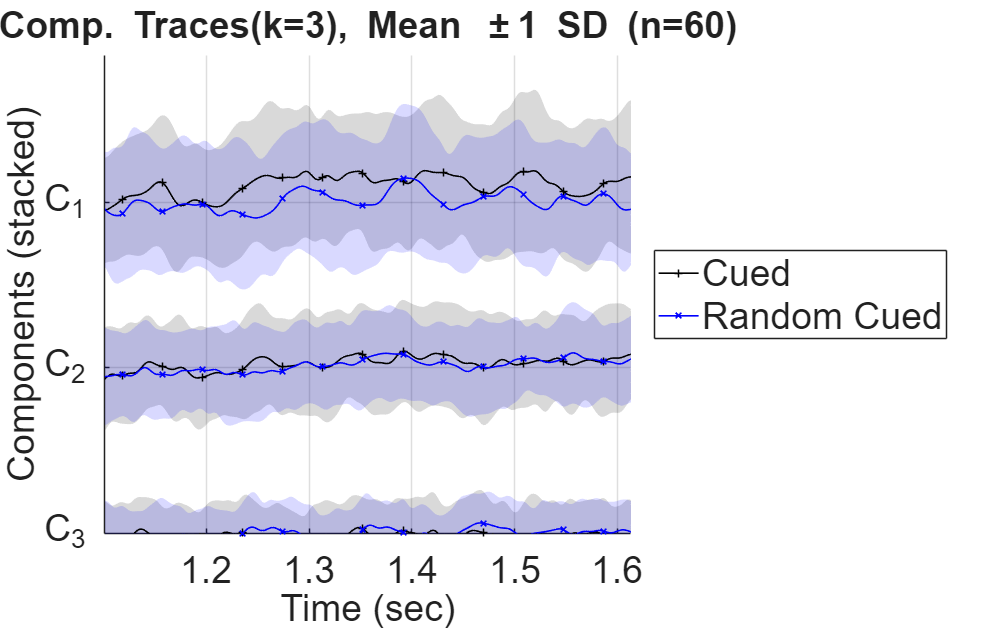

% plot the average component traces with standard deviation
%% 3.0 Overlapping Mean Component Traces (Baseline vs. Cued)
num_comps_plot = k;

% Calculate dynamic offset based on peak-to-peak ranges
y_range = max(Z_dpca_all_mean, [], 2) - min(Z_dpca_all_mean, [], 2);
offset = max(y_range) * 3.5; 
if offset == 0 || isnan(offset), offset = 10; end 

% Setup Figure
fig2 = figure('Position', [50 50 1200 750]);
hold on;

% Create X-axis vector for the 'fill' shading (Using the 0.5 to 1.12s axis)
time_fill = [time_cropped_P13, fliplr(time_cropped_P13)];

for pc = 1:num_comps_plot
    % Calculate vertical shift for stacking (Component 1 at the top)
    y_shift = (num_comps_plot - pc) * offset;
    
    % --- Split and Shift Means ---
    mean_P1 = Z_dpca_all_mean(pc, 1:nTime_single) + y_shift;
    mean_P3  = Z_dpca_all_mean(pc, nTime_single+1:end) + y_shift;
    
    % --- Split Standard Deviations ---
    std_P1 = Z_dpca_all_std(pc, 1:nTime_single);
    std_P3  = Z_dpca_all_std(pc, nTime_single+1:end);
    
    % --- Calculate Shading Bounds ---
    bound_P1 = [mean_P1 + std_P1, fliplr(mean_P1 - std_P1)];
    bound_P3  = [mean_P3 + std_P3, fliplr(mean_P3 - std_P3)];
    
    % 1. Plot Shaded Standard Deviation Areas 
    % (Using FaceAlpha 0.15 so overlapping shadows don't black out the plot)
    fill(time_fill, bound_P1, 'k', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    fill(time_fill, bound_P3, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    
    % 2. Plot Solid Mean Lines with Markers
    % (MarkerIndices spaces the markers out every 20 samples to avoid clumping)
    marker_spacing = 1:20:length(time_cropped_P13);
    
    plot(time_cropped_P13, mean_P1, 'Color', 'k', 'Marker', '+', 'LineWidth', 1.2, ...
        'MarkerIndices', marker_spacing, 'HandleVisibility', 'off');
        
    plot(time_cropped_P13, mean_P3, 'Color', 'b', 'Marker', 'x', 'LineWidth', 1.2, ...
        'MarkerIndices', marker_spacing, 'HandleVisibility', 'off');
end

% --- Dummy handles for the Legend ---
h_P1 = plot(NaN, NaN, 'Color', 'k', 'Marker', '+', 'LineWidth', 1.2, 'DisplayName', 'Cued');
h_P3  = plot(NaN, NaN, 'Color', 'b', 'Marker', 'x', 'LineWidth', 1.2, 'DisplayName', 'Random Cued');

hold off;

% --- Formatting ---
ylim([-offset/2, num_comps_plot * offset]);
xlim([min(time_cropped_P13), max(time_cropped_P13)]); 
% xticks([1, 1.5, 2, 2.5, 3]);
xlabel('Time (sec)');
ylabel('Components (stacked)');

% Dynamic title displaying k and trial count
title(['Comp. Traces(k=' num2str(num_comps_plot) '), Mean \pm1 SD (n=' num2str(size(data_concat_all, 3)) ')']);

% Set ascending ticks to show component numbers clearly
yticks((0:num_comps_plot-1) * offset);
yticklabels(arrayfun(@(c) sprintf('C_{%d}', num_comps_plot - c), ...
    0:num_comps_plot-1, 'UniformOutput', false));

legend([h_P1, h_P3], 'Location', 'eastoutside');
grid on;
set(findall(fig2, '-property', 'FontSize'), 'FontSize', 28);